clear all;
A = [0, 1, 0;
    0, 0, 1;
    -2, -3, -5];
B = [0;
    0;
    1];
C = [1, 0, 0];
D = 0;
sys = ss(A,B,C,D);

rank(ctrb(sys))

ans = 3

rank(obsv(sys))

ans = 3

% 퍼포먼스 기준
zeta = 0.8;
wn = 6;

poly1 = [1 2*zeta*wn wn^2]

poly1 =     1.0000    9.6000   36.0000


poly2 = [1 zeta*wn]

poly2 =     1.0000    4.8000


poly = conv(poly1,poly2)

poly =     1.0000   14.4000   82.0800  172.8000


root = roots(poly)

root =   -4.8000 + 3.6000i
  -4.8000 - 3.6000i
  -4.8000 + 0.0000i



K = place(A,B,root) % 애커만

K =   170.8000   79.0800    9.4000


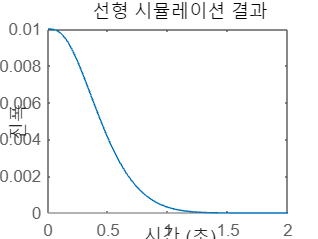

sys_cl = ss(A-B*K,B,C,D);
t = 0:0.01:2;
u = zeros(size(t));
x0 = [0.01, 0, 0];
lsim(sys_cl, u, t, x0)

% pole이 주어졌을 때 기준
r1 = -10 + 10i;
r2 = -10 - 10i;
r3 = -50;
K = place(A,B, [r3,r2,r1])

K = 1.0e+03 *

    9.9980    1.1970    0.0650


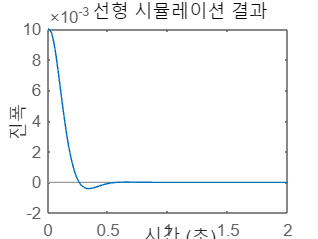

sys_cl = ss(A-B*K,B,C,D);
t = 0:0.01:2;
u = zeros(size(t));
x0 = [0.01, 0, 0];
lsim(sys_cl, u, t, x0)

% 전달함수일때
clearvars;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


G = 1/s^2;
[A,B,C,D] = ssdata(ss(G))

A =      0     0
     1     0


B =      1
     0


C =      0     1


D = 0

r1 = -1 + 1i;
r2 = -1 - 1i;
K = place(A,B,[r1, r2]);

sys_cl = ss(A-B*K,B,C,D);
t = 0:0.01:10;
u = zeros(size(t));
x0 = [0 0.01] % C에서 [0 1] 이었으니까

x0 =          0    0.0100


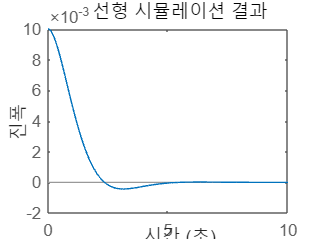

lsim(sys_cl,u,t,x0)